# Examples and Applications of Root Loci  

## Introduction

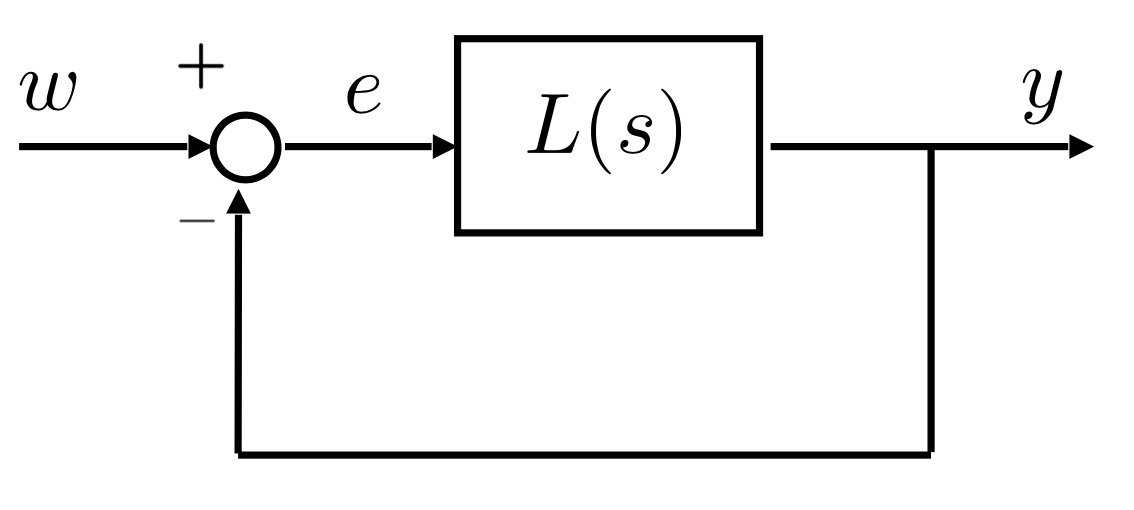

With this live script, we want to illustrate how one can draw a **root** **locus** in MATLAB and also determine some characteristic points, such as the **centroid** of the **asymptotes**, the slope **angles** of the asymptotes, and the **singular** **points** of the locus (points belonging to multiple branches of the root locus).

clear

s = tf('s'); 


## A Recap: Singular Points, Angles & Centroid of the Asymptotes

We refer to the parameterisation of $L(s)$ using poles and zeros (refer to slide Part4, 28 fo the course material)


$$L(s) = \varrho \,\frac{\prod_{j=1}^{m} (s+z_j)}{\prod_{i=1}^{n} (s+p_i)}\;, \quad m \le n$$


The Root Locus diagram shows the roots of


$$1+L(s)=0 \quad \Longleftrightarrow \quad 1+ \varrho\,\frac{\prod_{j=1}^{m} (s+z_j)}{\prod_{i=1}^{n} (s+p_i)} = 0 \quad \Longleftrightarrow \quad \,\frac{\prod_{j=1}^{m} (s+z_j)}{\prod_{i=1}^{n} (s+p_i)} = -\frac{1}{\varrho} \quad (\star)$$


in the complex plane for all $\varrho \in \mathbb{R}$, $\varrho \ne 0$.

### The Singular Points of a Root Locus

Let's rewrite Eq. $(\star)$ as 


$$\varrho = - \frac{\prod_{i=1}^{n} (s+p_i) }{\prod_{j=1}^{m} (s+z_j)} = \gamma (s)$$


If we consider $s=x,\, x \in \mathbb{R}$, then the **singular** **points** (or **breakaway/break-in points**) of the **root locus**, belonging to the real axis of the complex plane, are the **stationary points of **$\gamma(x)$ such that


$$\bar{x} \in \mathbb{R}: \left. \frac{d\,\gamma(x)}{dx} \right|_{x=\bar{x}} = 0,\; \gamma(x) = - \left. \frac{\prod_{i=1}^{n} (s+p_i) }{\prod_{j=1}^{m} (s+z_j)} \right|_{s=x,\,x\in \mathbb{R}}\qquad (+)$$


Note: given a singular point $\bar x$, the corresponding value of $\varrho$ can be computed simply as


$$\bar{\varrho} = \gamma(\bar x) = - \frac{\prod_{i=1}^{n} (\bar{x}+p_i) }{\prod_{j=1}^{m} (\bar{x}+z_j)}$$


Let's rewrite Eq. $(+)$:


$$\gamma(x) = - \left. \frac{\prod_{i=1}^{n} (x+p_i) }{\prod_{j=1}^{m} (x+z_j)} \; \Longrightarrow \; \frac{d\,\gamma(x)}{dx}  =0 \; \longleftrightarrow \; \left[ \prod_{j=1}^{m} (x+z_j) \right] \cdot \frac{d\;}{dx} \left( \prod_{i=1}^{n} (x+p_i)  \right) - \left[  \prod_{i=1}^{n} (x+p_i)  \right] \cdot \frac{d\;}{dx} \left(  \prod_{j=1}^{m} (x+z_j)  \right) = 0$$


By solving Eq. $(+)$, do we find every singular point of the locus? In general no, not always!

A generic point $\hat{s} \in \mathbb{C}$belongs to the root locus described by  Eq. $(\star)$ if and only if there exists a real value $\hat \varrho$ such that


$$\frac{\prod_{j=1}^{m} (\hat{s}+z_j)}{\prod_{i=1}^{n} (\hat{s}+p_i)} = -\frac{1}{\hat{\varrho}}$$


Thus, a candidate singular point $\tilde{s} \in \mathbb{C}$ solution of


$$\tilde{s} \in \mathbb{C}: \left. \frac{d\,\gamma(s)}{d} \right|_{s=\tilde{s}} = 0,\; \gamma(s) = - \frac{\prod_{i=1}^{n} (s+p_i) }{\prod_{j=1}^{m} (s+z_j)} \qquad (*)$$


is a true singular point if the corresponding value $\tilde{\varrho} = \gamma(\tilde{s})$ is **real**.

- Candidate singular points (i.e. solutions of  Eq. $(*)$ ), which are real values, are for sure singular points.

- Candidate complex-valued singular points $\tilde{s}$ must be checked: they are actual singular points if and only if $\tilde{\varrho} = \gamma(\tilde{s}) \in \mathbb{R}$.

- This does not seem to be an efficient strategy.

Let's rewrite Eq $(*)$:


$$\gamma(s) = - \left. \frac{\prod_{i=1}^{n} (s+p_i) }{\prod_{j=1}^{m} (s+z_j)} \; \Longrightarrow \; \frac{d\,\gamma(s)}{ds}  =0 \; \longleftrightarrow \; \left[ \prod_{j=1}^{m} (s+z_j) \right] \cdot \frac{d\;}{ds} \left( \prod_{i=1}^{n} (s+p_i)  \right) - \left[  \prod_{i=1}^{n} (s+p_i)  \right] \cdot \frac{d\;}{ds} \left(  \prod_{j=1}^{m} (s+z_j)  \right) = 0 \qquad (**)$$


#### **Multiple Zeros and Poles as Singular Points**

- Every **open-loop pole/zero** with **multiplicity greater than 1** is a **singular point **of the root locus (easy to prove from Eq. $(*)$ ).

- Example: let $-p_k$ be a pole with algebraic multiplicity 2 

       
$$ \prod_{i=1}^{n} (s+p_i)  = \left(s+ p_k\right)^2\, \prod_{i \ne k }(s+p_i) $$


Thus


$$\left[ \prod_{j=1}^{m} (s+z_j) \right] \cdot \frac{d\;}{ds} \left( \prod_{i=1}^{n} (s+p_i)  \right) - \left[  \prod_{i=1}^{n} (s+p_i)  \right] \cdot \frac{d\;}{ds} \left(  \prod_{j=1}^{m} (s+z_j)  \right) = 0 \;\Longleftrightarrow \;
\left[ \prod_{j=1}^{m} (s+z_j) \right] \cdot \frac{d\;}{ds} \left(  \left(s+ p_k\right)^2\, \prod_{i \ne k }(s+p_i)   \right) - \left[   \left(s+ p_k\right)^2\, \prod_{i \ne k }(s+p_i)  \right] \cdot \frac{d\;}{ds} \left(  \prod_{j=1}^{m} (s+z_j)  \right) = 0 $$


Then


$$\left[ \prod_{j=1}^{m} (s+z_j) \right] \cdot \left\{2\left(s+ p_k\right)\,\left[ \prod_{i \ne k }(s+p_i)   \right]  +  \left(s+ p_k\right)^2\,\frac{d\;}{d\,s} \left[ \prod_{i \ne k }(s+p_i)   \right] \right\} - \left[   \left(s+ p_k\right)^2\, \prod_{i \ne k }(s+p_i)  \right] \cdot \frac{d\;}{ds} \left(  \prod_{j=1}^{m} (s+z_j)  \right) = 0 $$


So, $s=-p_k$ is a solution of the polynomial equation.

**Important Remark**

-  If the open-loop pole/zero with multiplicity greater than 1 is real-valued, it is the solution of  Eq. $(+)$.

- Otherwise, if complex, it is one of the solutions of Eq. $(*)$, which is an effective singular point of the locus.

- In the latter case, by efficiently exploiting this property, we have successfully determined the singular points of the locus that do not belong to the real axis without the need to solve Eq. $(*)$ directly.

#### Examples


$$L_1(s) = \varrho \frac{(s+1)^2}{(s+4)^2} \qquad L_2(s) = \varrho\, \frac{(s+1)^2(s+2)}{(s^2+2s+9)^2}$$


### A Different Expression for the Singular Points Equation

You can manipulate Eq. $(**)$ to obtain an additional expression for the singular points equation.

Let's define


$$L(s) = \frac{\prod_{j=1}^{m} (s+z_j)}{\prod_{i=1}^{n} (s+p_i)}  = \frac{N(s)}{\varphi(s)}$$


Thus, you can rewrite Eq, $(**)$ as


$$N(s) \cdot \frac{d\;}{ds} \Big\{\varphi(s) \Big\} - \varphi(s) \cdot \frac{d\;}{ds} \Big\{ N(s) \Big\} = 0 \; \Longleftrightarrow \; \varphi(s) \cdot \frac{d\;}{ds} \Big\{ N(s) \Big\} - N(s) \cdot \frac{d\;}{ds} \Big\{\varphi(s) \Big\} = 0 \;
\Longleftrightarrow \; \frac{d\;}{d\,s} \Big[L(s) \Big] = 0 \qquad (**ALT)$$


This formulation could be helpful if you don't have the factorised form for the polynomials in the numerator and denominator in $L(s)$.

## With a Little Help from the 'help' Command!

Here is the documentation related to the *Control System Toolbox* function we will use in this live script:

help rlocus

 rlocus - Root locus of dynamic system
    This MATLAB function calculates the root locus of SISO model sys and
    returns the resulting vector of feedback gains k and corresponding
    complex root locations r.

    Syntax
      [r,kout] = rlocus(sys)
      r = rlocus(sys,k)

      rlocus(___)

    Input Arguments
      sys - Dynamic system
        dynamic system model | model array
      k - Feedback gain values
        vector

    Output Arguments
      r - Closed-loop pole locations
        array
     


help rloclims

 rloclims  Compute adequate axis limits for root loci with asymptotes.
 
    [XLIMS,YLIMS] = rloclims(R) returns the X and Y axis limits 
    vectors given the set of roots R (arranged column-wise).
 
    See also rlocus.




help rlocfind

 rlocfind  Find root locus gains for a given set of roots.
 
    [K,POLES] = rlocfind(SYS)  is used for interactive gain 
    selection from the root locus plot of the SISO system SYS 
    generated by RLOCUS.  rlocfind puts up a crosshair cursor 
    in the graphics window which is used to select a pole location 
    on an existing root locus.  The root locus gain associated 
    with this point is returned in K and all the system poles for 
    this gain are returned in POLES.  
 
    [K,POLES] = rlocfind(SYS,P)  takes a vector P of desired root 
    locations and computes a root locus gain for each of these 
    locations (i.e., a gain for which one of the closed-loop roots
    is near the desired location).  The j-th entry of the vector K
    gives the computed gain for the location P(j), and the j-th 
    column of the matrix POLES lists the resulting closed-loop poles.
 
    See also  


help rlocusplot

--- help for controllib.chart.RLocusPlot ---

 controllib.chart.RLocusPlot - Root locus plot of dynamic system
    The rlocusplot function plots the root locus of a dynamic system model
    and returns an RLocusPlot chart object.

    Creation
      Syntax
        rlp = rlocusplot(sys)
        rlp = rlocusplot(sys1,sys2,...,sysN)
        rlp = rlocusplot(sys1,LineSpec1,...,sysN,LineSpecN)
        np = rlocus(___,k)

        rlp = rlocusplot(___,plotoptions)

        rlp = rlocusplot(parent,___)

      Input Arguments
        sys - Dynamic system
          dynamic system model | model array
        LineSpec - Line style, marker, and color
          st


help sgrid

 sgrid - Generate s-plane grid of constant damping factors and natural frequencies
    This MATLAB function generates a grid of constant damping factors from 0
    to 1 in steps of 0.1 and natural frequencies from 0 to 10 rad/sec in
    steps of one rad/sec for pole-zero and root locus plots.

    Syntax
      sgrid
      sgrid(zeta,wn)
      sgrid(___,'new')
      sgrid(AX,___)

    Input Arguments
      zeta - Damping ratio
        vector
      wn - Normalized natural frequency
        vector
      AX - Object handle
        Axes ob

## Example: a Direct Root Locus

Consider the following block diagram

where $L(s)$ is the transfer function


$$L(s) = \varrho \frac{s+1}{s^2}\;, \varrho \in \mathbb{R},\, \varrho>0$$


Let's determine the **Direct RL** in MATLAB.

- **The first step**: write the closed-loop equation as


$$1+L(s) = 0 \quad \Longrightarrow \quad 1+\varrho\,\frac{\prod_{j=1}^{m} (s+z_j)}{\prod_{i=1}^{n} (s+p_i)} =0 \quad \Longrightarrow \quad 
\frac{\prod_{j=1}^{m} (s+z_j)}{\prod_{i=1}^{n} (s+p_i)} = -\frac{1}{\varrho}$$


- **Notice** that the last expression separates the variable parameter ( $\varrho$  in the example) from the transfer function expression. This form of the closed-loop pole equation will be used to determine the expression of the transfer function to be entered into the MATLAB functions, allowing us to plot the required root locus. 


$$1+ \varrho \frac{s+1}{s^2}= 0 \quad 
\Longrightarrow \quad \frac{s+1}{s^2} = -\frac{1}{\varrho}$$


Thus the transfer function we will use in MATLAB is:

L1s = (s+1)/s^2


L1s =
 
  s + 1
  -----
   s^2
 
Continuous-time transfer function.
Model Properties


### Zeros & Poles

- **The second step**: compute the open-loop zeros and poles. 

- Are there zeros or poles with multiplicity greater than 1? 

Simply

zL1 = zero(L1s)

zL1 = -1


pL1 = pole(L1s)

pL1 =      0
     0


**Notice** the pole at the origin $p_1=0$, with multiplicity $n_1=2$. Thus it is a **singular** **point**!

### Singular Points

- **The third step**: determine the **set of singular points** of the root locus, by solving Eq. $(+)$ and looking for  open-loop complex-valued zeros/poles with multiplicity greater than 1.


$$L_1(s) =  \frac{s+1}{s^2} \quad \Longrightarrow \quad \gamma(x) = -  \frac{x^2 }{x+1},\; x \in \mathbb{R} \quad \Longrightarrow \quad
\frac{d\, \gamma(x)}{dx} = 0 \Longleftrightarrow \quad 
\frac{d\;}{dx} \left[-\frac{x^2 }{x+1}\right] = 0$$


syms x real
syms gamma(x)
gamma(x) = -x^2/(x+1)

$$gamma(x) = -\frac{x^{2}}{x+1}$$

dot_g(x) = simplify(collect(diff(gamma,x),x))

$$dot\_g(x) = -\frac{x\,\left(x+2\right)}{{\left(x+1\right)}^{2}}$$

breakP_candidate = solve(dot_g==0)

$$breakP\_candidate = \left(\begin{array}{c} -2\\ 0 \end{array}\right)$$

breakP_C1 = breakP_candidate(1);
breakP_C2 = breakP_candidate(2);


**Note**: by solving Eq. $(+)$ we found also the pole $p_1=0$ as singular point (we already knew this).

**Question 1**: To which root locus does the singular point $x_1=0$ belong?

**Question 2**: To which root locus does the other singular point candidate belong?

if (gamma(breakP_C1) >0)
   fprintf('x = %.2f is a singular point of the Direct RL.\n', breakP_C1);
else
    fprintf('x = %.2f is a singular point of the Inverse RL.\n', breakP_C1);
end

x = -2.00 is a singular point of the Direct RL.



breakPs = double(breakP_candidate);

### Centroid & Asymptotes

Given


$$L(s) = \varrho\,\frac{\prod_{j=1}^{m} (s+z_j)}{\prod_{i=1}^{n} (s+p_i)} ,\; \varrho \in \mathbb{R},\; m < n$$


the center of the asymptotes (named **centroid**) is 


$$x_a = \frac{1}{n-m} \left[ \sum_{j=1}^{m} z_j - \sum_{i=1}^{n} p_i \right]$$


and the $(n-m)$ asymptotes (of the Direct RL) form the following angles with the real axis


$$\psi_a = \frac{(2k+1)\cdot 180^{\circ}}{n-m},\;k=0,\,1,\,\ldots ,\, n-m-1$$


Thus, the centroid is

n = numel(pL1); % the degree of the polynomial at the denominator in the TF
m = numel(zL1); % the degree of the polynomial at the nuumerator in the TF

% the centroid
x_a = (1/(n-m))*(sum(pL1) - sum(zL1))

x_a = 1

and the asymptotes of the DL form the angles

k = (0:n-m-1);
theta_a = (180/(n-m))*(2.*k+1)

theta_a = 180

### The Direct Locus

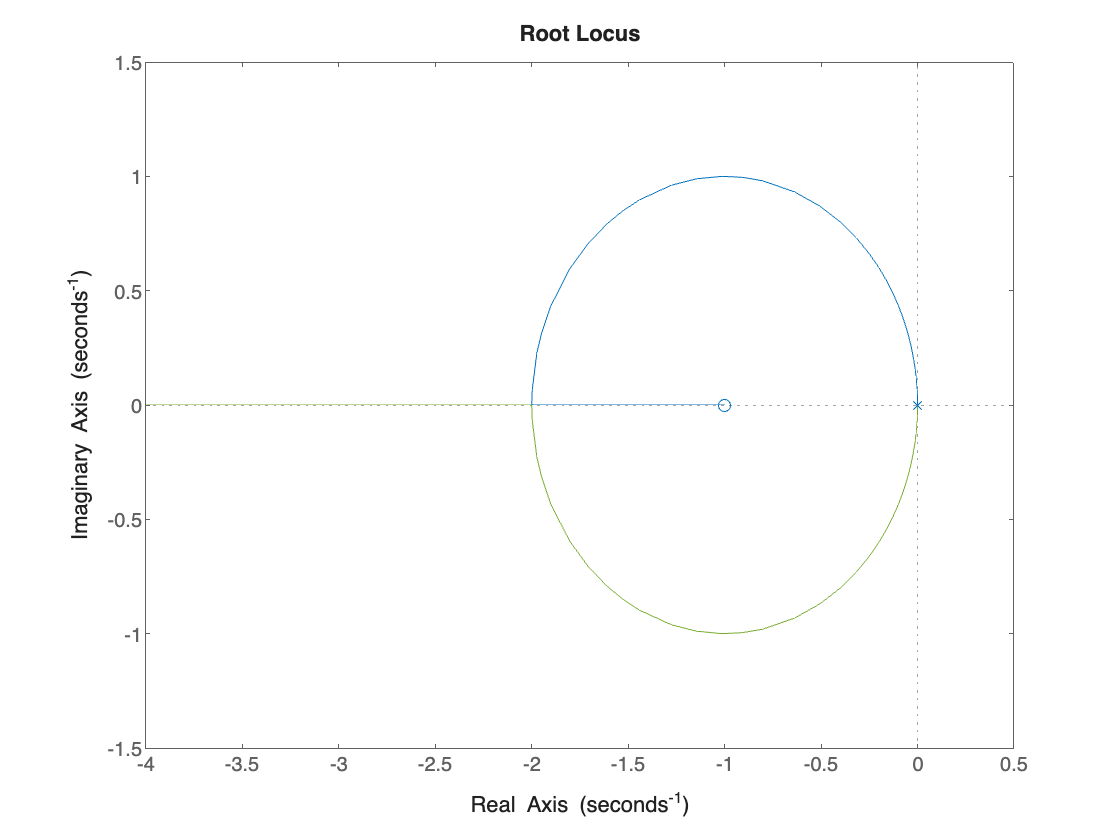

figure;rlocus(L1s);

Select a point in the graphics window


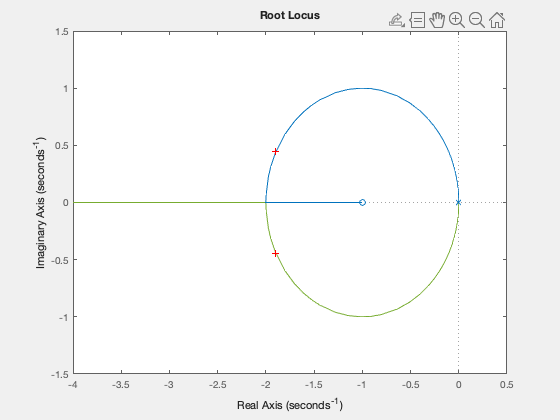

selected_point = -1.8589 + 0.4286i

KK = 3.7913

cc_poles =   -1.8956 + 0.4448i
  -1.8956 - 0.4448i


[KK, cc_poles] = rlocfind(L1s)

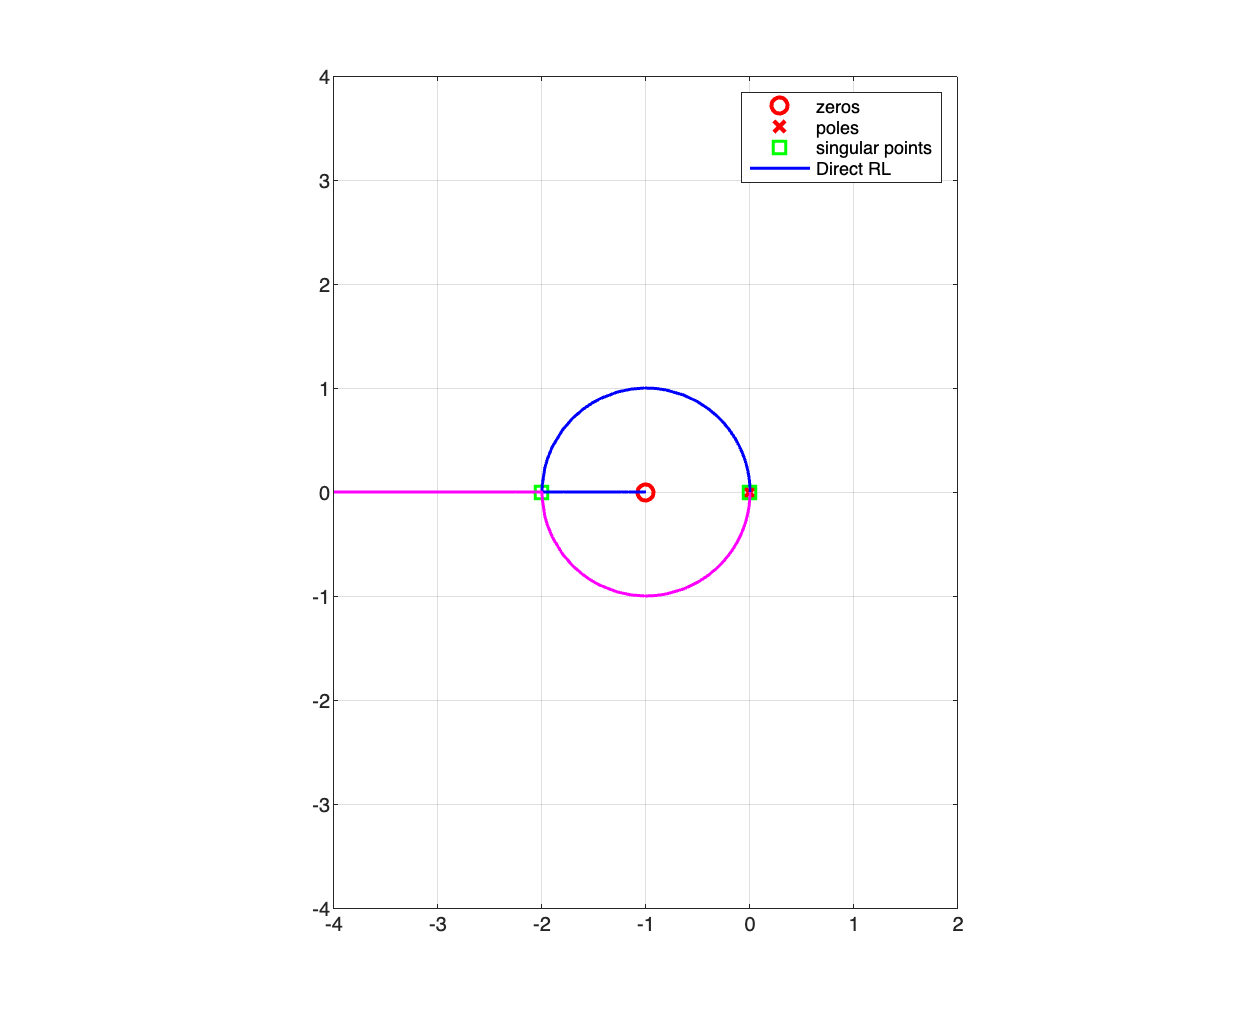


RL1 = rlocus(L1s); 
% note the structure of RL1: array(n, p)
% where n <--> number of branches (i.e. the degree of the polynomial at
%              denominator)
%       p <--> number of points (closed-loop poles) belonging to each
%              branch, i.e. number of values fo the gain rho used to
%              determine the Direct Locus
figure('Units','centimeters','Position',[0.1, 0.1, 22, 18]);
% let's start with zeros & poles and then singular points
h_s1 = plot(real(zL1),imag(zL1),'ro', ...
    real(pL1),imag(pL1),'rx', ...
    real(breakPs), imag(breakPs), 'gs', ...
    'MarkerSize',8, 'LineWidth',2); hold on;

% the Direct RL
h_rld1 = plot( real(RL1(1,:)),imag(RL1(1,:)),'b', ...
   real(RL1(2,:)),imag(RL1(2,:)),'m', ...
  'LineWidth',1.5 );

grid on; hold off; axis equal;
axis([-4,2,-4, 4]); 
legend([h_s1;h_rld1(1)],'zeros','poles','singular points','Direct RL')

What about the Inverse Root Locus?

What about closed-loop performance?

## Hands-on Examples

Determine the **Direct** and the **Inverse** **Root** **Locus** for the transfer functions


$$L_a(s) = \frac{(s+1)^2}{(s+2)^4} \qquad L_b(s) = \frac{(s+1)^2}{(s-1)^3} \qquad L_c(s) = \frac{s+4}{s\,\left(s^2+s+\frac{5}{4}\right)\,(s+2)^2}$$


## Closed-Loop Performance Analysis Using Root Locus

### A First Example

Consider the block diagram

where $L(s)$ is the transfer function


$$L(s) = \varrho \frac{s+6}{(s+1)^2}\;, \varrho \in \mathbb{R},\, \varrho>0$$


Let's vary the gain $\varrho$: what about the closed-loop performance and stability? Can we infer the step-response features when increasing the gain? Can we infer the stability margins? 

clear variables
s = tf('s');

% the transfer function L(s)
L1s = (s+6)/((s+1)^2);

% zeros & poles
zL1 = zero(L1s);
pL1 = pole(L1s);

% asymptotes & centroid
n = numel(pL1); % the degree of the polynomial at the denominator in the TF
m = numel(zL1); % the degree of the polynomial at the nuumerator in the TF
% the centroid
x_a = (1/(n-m))*(sum(pL1) - sum(zL1))

x_a = 4

% the asymptotes belonging to the DL
k = (0:n-m-1);
theta_a = (180/(n-m))*(2.*k+1)

theta_a = 180

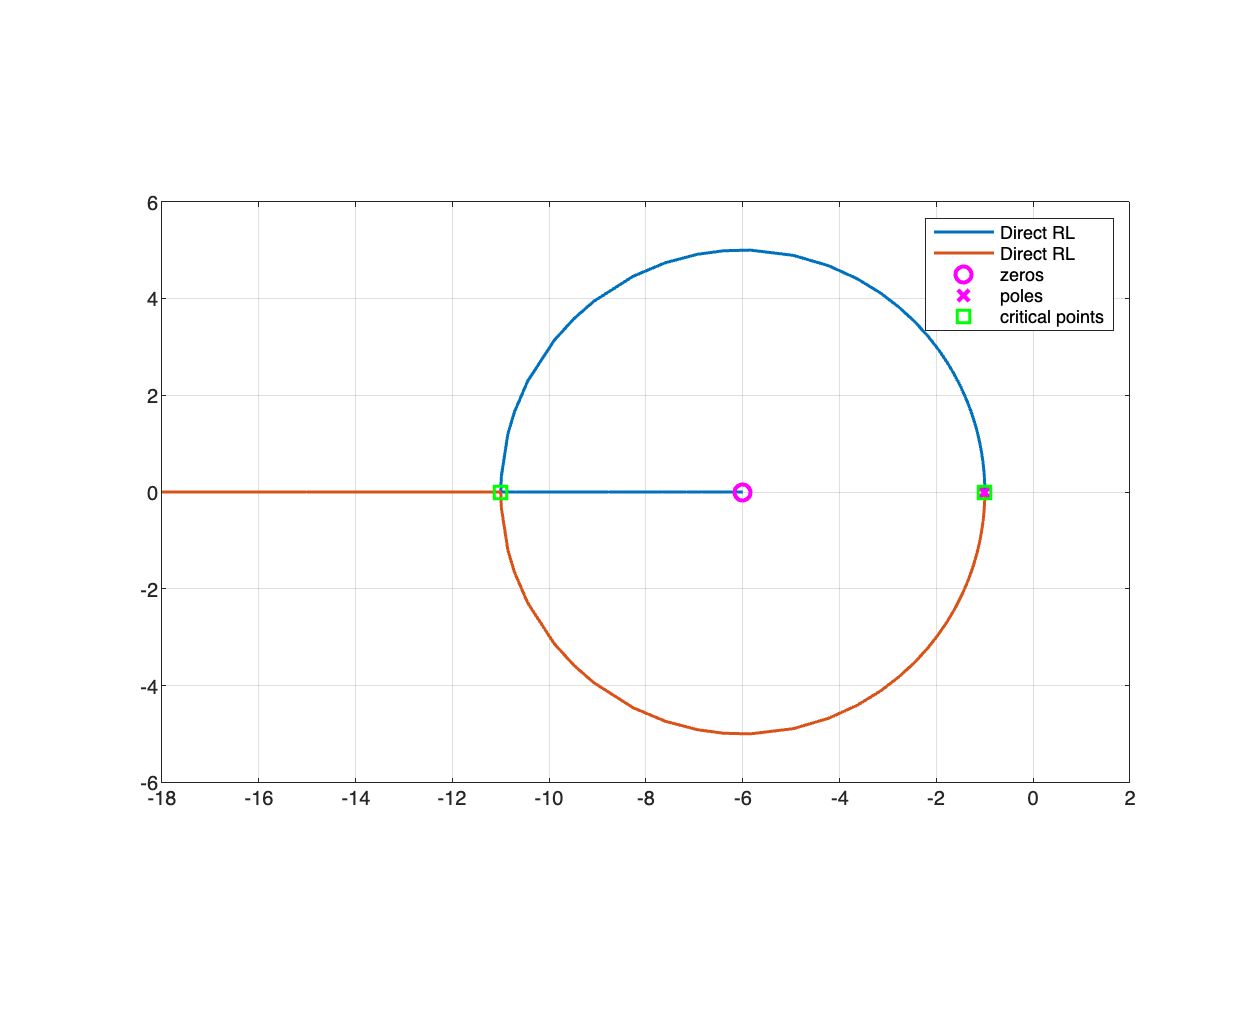


% =========================================================
% Let's determine the critical points using the Eq. (**ALT) 
criticalPoints = DetermineCriticalPointsRL(L1s);
cP_DLset = checkCriticPointsDL(criticalPoints, L1s);
% Which critical point belongs to the Direct Root Locus?
% =========================================================

RL1 = rlocus(L1s); 
% note the structure of RL1: array(n, p)
% where n <--> number of branches (i.e. the degree of the polynomial at
%              denominator)
%       p <--> number of points (closed-loop poles) belonging to each
%              branch, i.e. number of values fo the gain rho used to
%              determine the Direct Locus
hfRL1 = figure('Units','centimeters','Position',[0.1, 0.1, 22, 18]);
% the Direct RL
n = size(RL1, 1); % how many branches?
for k=1:n
    h_rld1(k,1) = plot( real(RL1(k,:)),imag(RL1(k,:)),'LineWidth',1.5 );
    hold on;
end % for k

% zeros & poles and then singular points
h_s1 = plot(real(zL1),imag(zL1),'mo', ...
    real(pL1),imag(pL1),'mx', ...
    real(cP_DLset), imag(cP_DLset), 'gs', ...
    'MarkerSize',8, 'LineWidth',2);

grid on; hold off; axis equal;
axis([-18,2,-6, 6]); 
LocusLeg = cell(1,n);
for k=1:n
    LocusLeg{1,k} = 'Direct RL';
end % for k
legend([LocusLeg, {'zeros','poles','critical points'}])

Let's consider a set of $\varrho$ values, visualise the corresponding closed-loop poles on the Direct Root Locus and investigate about the performance of the closed-loop system corresponding to each $\varrho$ value:

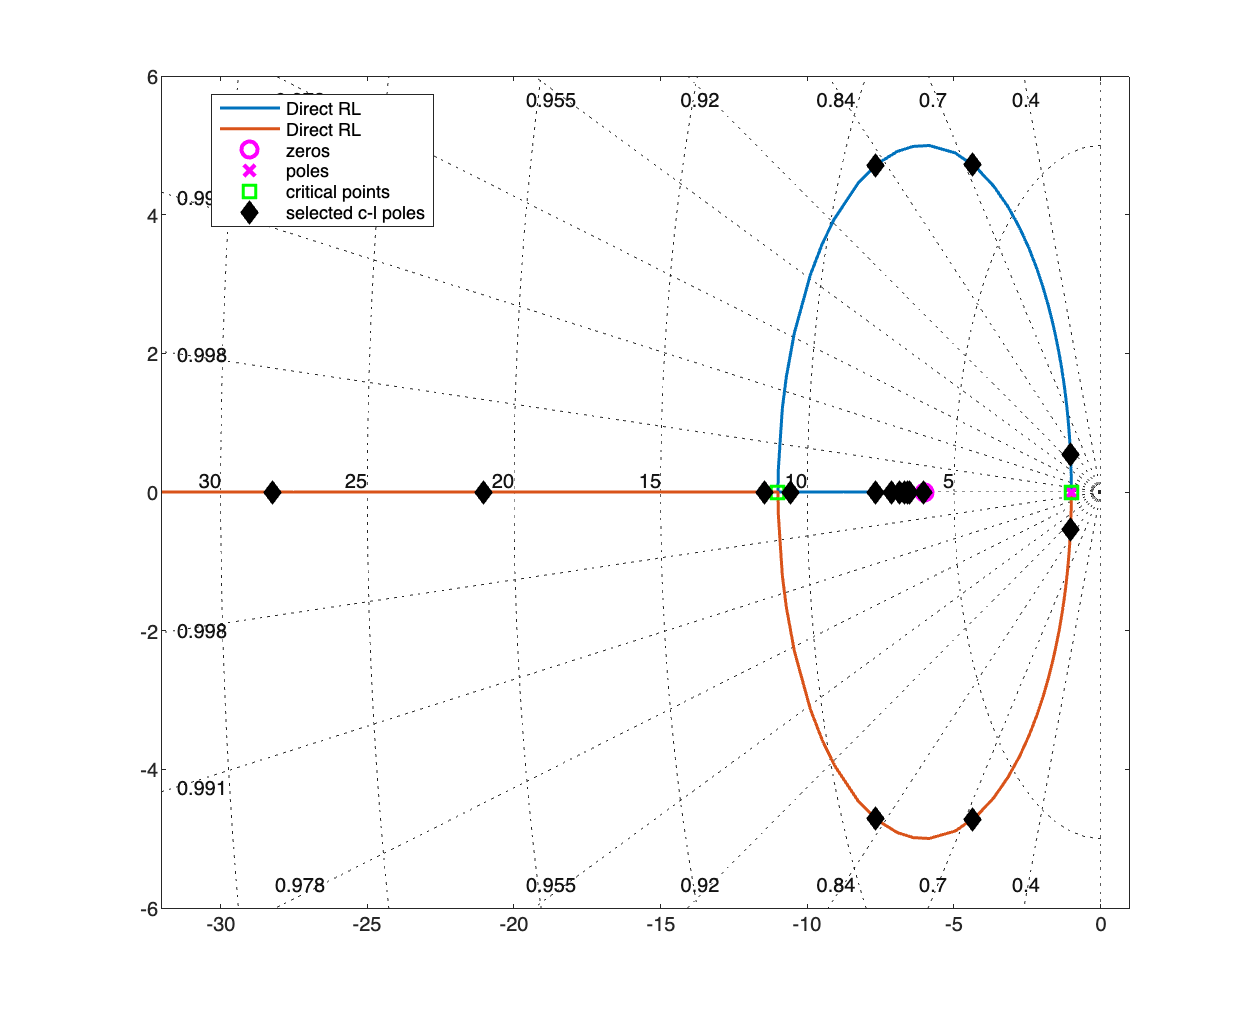

rhoSET = linspace(6e-2, 6.0e1, 10); % 20 values for the gain rho, from 10^(-2) to 10^4
rhoSET = [rhoSET, 1000];
closedLoopPoles = rlocus(L1s, rhoSET);

figure('Units','centimeters','Position',[0.1, 0.1, 22, 18]);
% the Direct RL
n = size(RL1, 1); % how many branches?
for k=1:n
    h_rld1(k,1) = plot( real(RL1(k,:)),imag(RL1(k,:)),'LineWidth',1.5 );
    hold on;
end % for k

% zeros & poles and then singular points
h_s1 = plot(real(zL1),imag(zL1),'mo', ...
    real(pL1),imag(pL1),'mx', ...
    real(cP_DLset), imag(cP_DLset), 'gs', ...
    'MarkerSize',8, 'LineWidth',2);

axis([-32,1,-6, 6]); 
LocusLeg = cell(1,n);
for k=1:n
    LocusLeg{1,k} = 'Direct RL';
end % for k

hold on;
n = size( closedLoopPoles,2);
for k=1:n
    hp = plot( real(closedLoopPoles(:,k)),imag(closedLoopPoles(:,k)), ...
   'LineStyle', 'none', 'Marker', 'diamond', 'MarkerSize', 8,...
   'MarkerEdgeColor','k', 'MarkerFaceColor','k');

end % for k
sgrid
hl = [h_rld1 ;h_s1; hp];
legend(hl,[LocusLeg, {'zeros','poles','critical points', 'selected c-l poles'}], 'Location', 'best')

#### Closed-Loop Performance Analysis

Let's determine the open-loop and the closed-loop transfer functions corresponding to each $\varrho$ value:

r = numel(rhoSET);
OL_tf = cell(r, 1); % to store the Open-Loop TFs
CL_tf = cell(r, 1); % to store the Closed-Loop TFs

for i=1:r
    OL_tf{i} = rhoSET(i)*L1s;
    CL_tf{i} = feedback(OL_tf{i}, 1, -1);
end % for i


Now, let's determine the performance for each transfer function.

STABmargins = cell(r, 1);
STEPperformance =  cell(r, 1);
CLpoles = cell(r, 1);

for ijk = 1:r
    [GmVAL,PmVAL,Wcg,Wcp] = margin(OL_tf{ijk} );
    STABmargins{ijk} = struct('Gm', GmVAL, ...
                               'GainFreq', Wcg, ...
                               'Pm', PmVAL, ...
                               'PhaseFreq', Wcp);
    CLpoles{ijk} = pole(CL_tf{ijk});
    res = stepinfo(CL_tf{ijk}, 'SettlingTimeThreshold',0.01);
    STEPperformance{ijk} = struct('RiseT', res.RiseTime, ...
                                   'SettlingT', res.SettlingTime, ...
                                   'OverShoot', res.Overshoot);
end % for ijk

Finally, let's fill a table with the results:

results = zeros(r, 8);

for m = 1:r
    results(m, 1) = rhoSET(m);

    results(m, 2) = STABmargins{m}.Pm;
    results(m, 3) = STABmargins{m}.PhaseFreq;
    results(m, 4) = STABmargins{m}.Gm;
    results(m, 5) = STABmargins{m}.GainFreq;

    results(m, 6) = STEPperformance{m}.SettlingT;
    results(m, 7) = STEPperformance{m}.OverShoot;
    results(m, 8) = STEPperformance{m}.RiseT;
    
    
end % for m

REStable1 = array2table([results(:,1),results(:,6:8)], "VariableNames",...
    {' Gain Rho', 'Step Resp. Settling Time', ...
     'Step Resp. Overshoot', 'Step Resp. Rise Time'})

REStable1 = 11×4 table
     Gain Rho    Step Resp. Settling Time    Step Resp. Overshoot    Step Resp. Rise Time
    _________    ________________________    ____________________    ____________________

       0.06                4.0031                  0.27598                    2.372      
       6.72               0.82451                   14.359                  0.17146      
      13.38                0.6254                   11.234                  0.10454      
      20.04               0.54411                   9.2235                 0.076874      
       26.7               0.49203                   7.8449                  0.06128      
      33.36               0.45212                   6.8435                 0.051168      
      40.02               0.41945                   6.0789                 0.043986      
      46.68               0.39


REStable2 = cell2table([num2cell(results(:,1)),CLpoles], "VariableNames",...
    {' Gain Rho', 'Closed-Loop Poles'})

REStable2 = 11×2 table
     Gain Rho    Closed-Loop Poles
    _________    _________________

       0.06        {2×1 double}   
       6.72        {2×1 double}   
      13.38        {2×1 double}   
      20.04        {2×1 double}   
       26.7        {2×1 double}   
      33.36        {2×1 double}   
      40.02        {2×1 double}   
      46.68        {2×1 double}   
      53.34        {2×1 double}   
         60        {2×1 double}   
       1000        {2×1 double}   


REStable3 = array2table([results(:,1:5)], "VariableNames",...
    {' Gain Rho', 'Phase Margin', 'Ph. Marg. Ang. Freq.', ...
     'Gaim Margin', 'G. Marg. Ang. Freq.'})

REStable3 = 11×5 table
     Gain Rho    Phase Margin    Ph. Marg. Ang. Freq.    Gaim Margin    G. Marg. Ang. Freq.
    _________    ____________    ____________________    ___________    ___________________

       0.06            Inf                 NaN               Inf                NaN        
       6.72         67.719              8.2036               Inf                NaN        
      13.38         75.344              14.422               Inf                NaN        
      20.04         79.418              20.808               Inf                NaN        
       26.7           81.8              27.301               Inf                NaN        
      33.36         83.333               33.85               Inf                NaN        
      40.02         84.393              40.433               Inf      

### A Second (Long) Example

Consider the block diagram

where $L(s)$ is the transfer function


$$L(s) = \varrho \frac{1}{(s+1)\,(s+3)}\;, \varrho \in \mathbb{R},\, \varrho>0$$


Let's vary the gain $\varrho$: what about the closed-loop performance and stability? Can we infer the step-response features when increasing the gain? Can we infer the stability margins? 

What happens if we modify the transfer function, multiplying the actual transfer function by another simple first-order term with a zero and a pole? Does performance improve or worsen?

Let's compare the performance of $L(s)$ with those obtained using the following transfer functions


$$L_a(s) = \varrho \frac{s+5}{(s+1)\,(s+3)\,(s+9)}\;, \varrho \in \mathbb{R},\, \varrho>0 \qquad L_b(s) = \varrho \frac{s+9}{(s+1)\,(s+3)\,(s+5)}\;, \varrho \in \mathbb{R},\, \varrho>0 $$


Which is the most performing closed-loop system?

clear variables
s = tf('s');

% the transfer function L(s)
L0s = 1/((s+1)*(s+3));

La_s = (s+5)/((s+1)*(s+3)*(s+9));
Lb_s = (s+9)/((s+1)*(s+3)*(s+5));

% zeros & poles
zL0 = zero(L0s);
pL0 = pole(L0s);

% asymptotes & centroid
n = numel(pL0); % the degree of the polynomial at the denominator in the TF
m = numel(zL0); % the degree of the polynomial at the nuumerator in the TF
% the centroid
x_a0 = (1/(n-m))*(sum(pL0) - sum(zL0))

x_a0 = -2

% the asymptotes belonging to the DL
k = (0:n-m-1);
theta_a0 = (180/(n-m))*(2.*k+1)

theta_a0 =     90   270


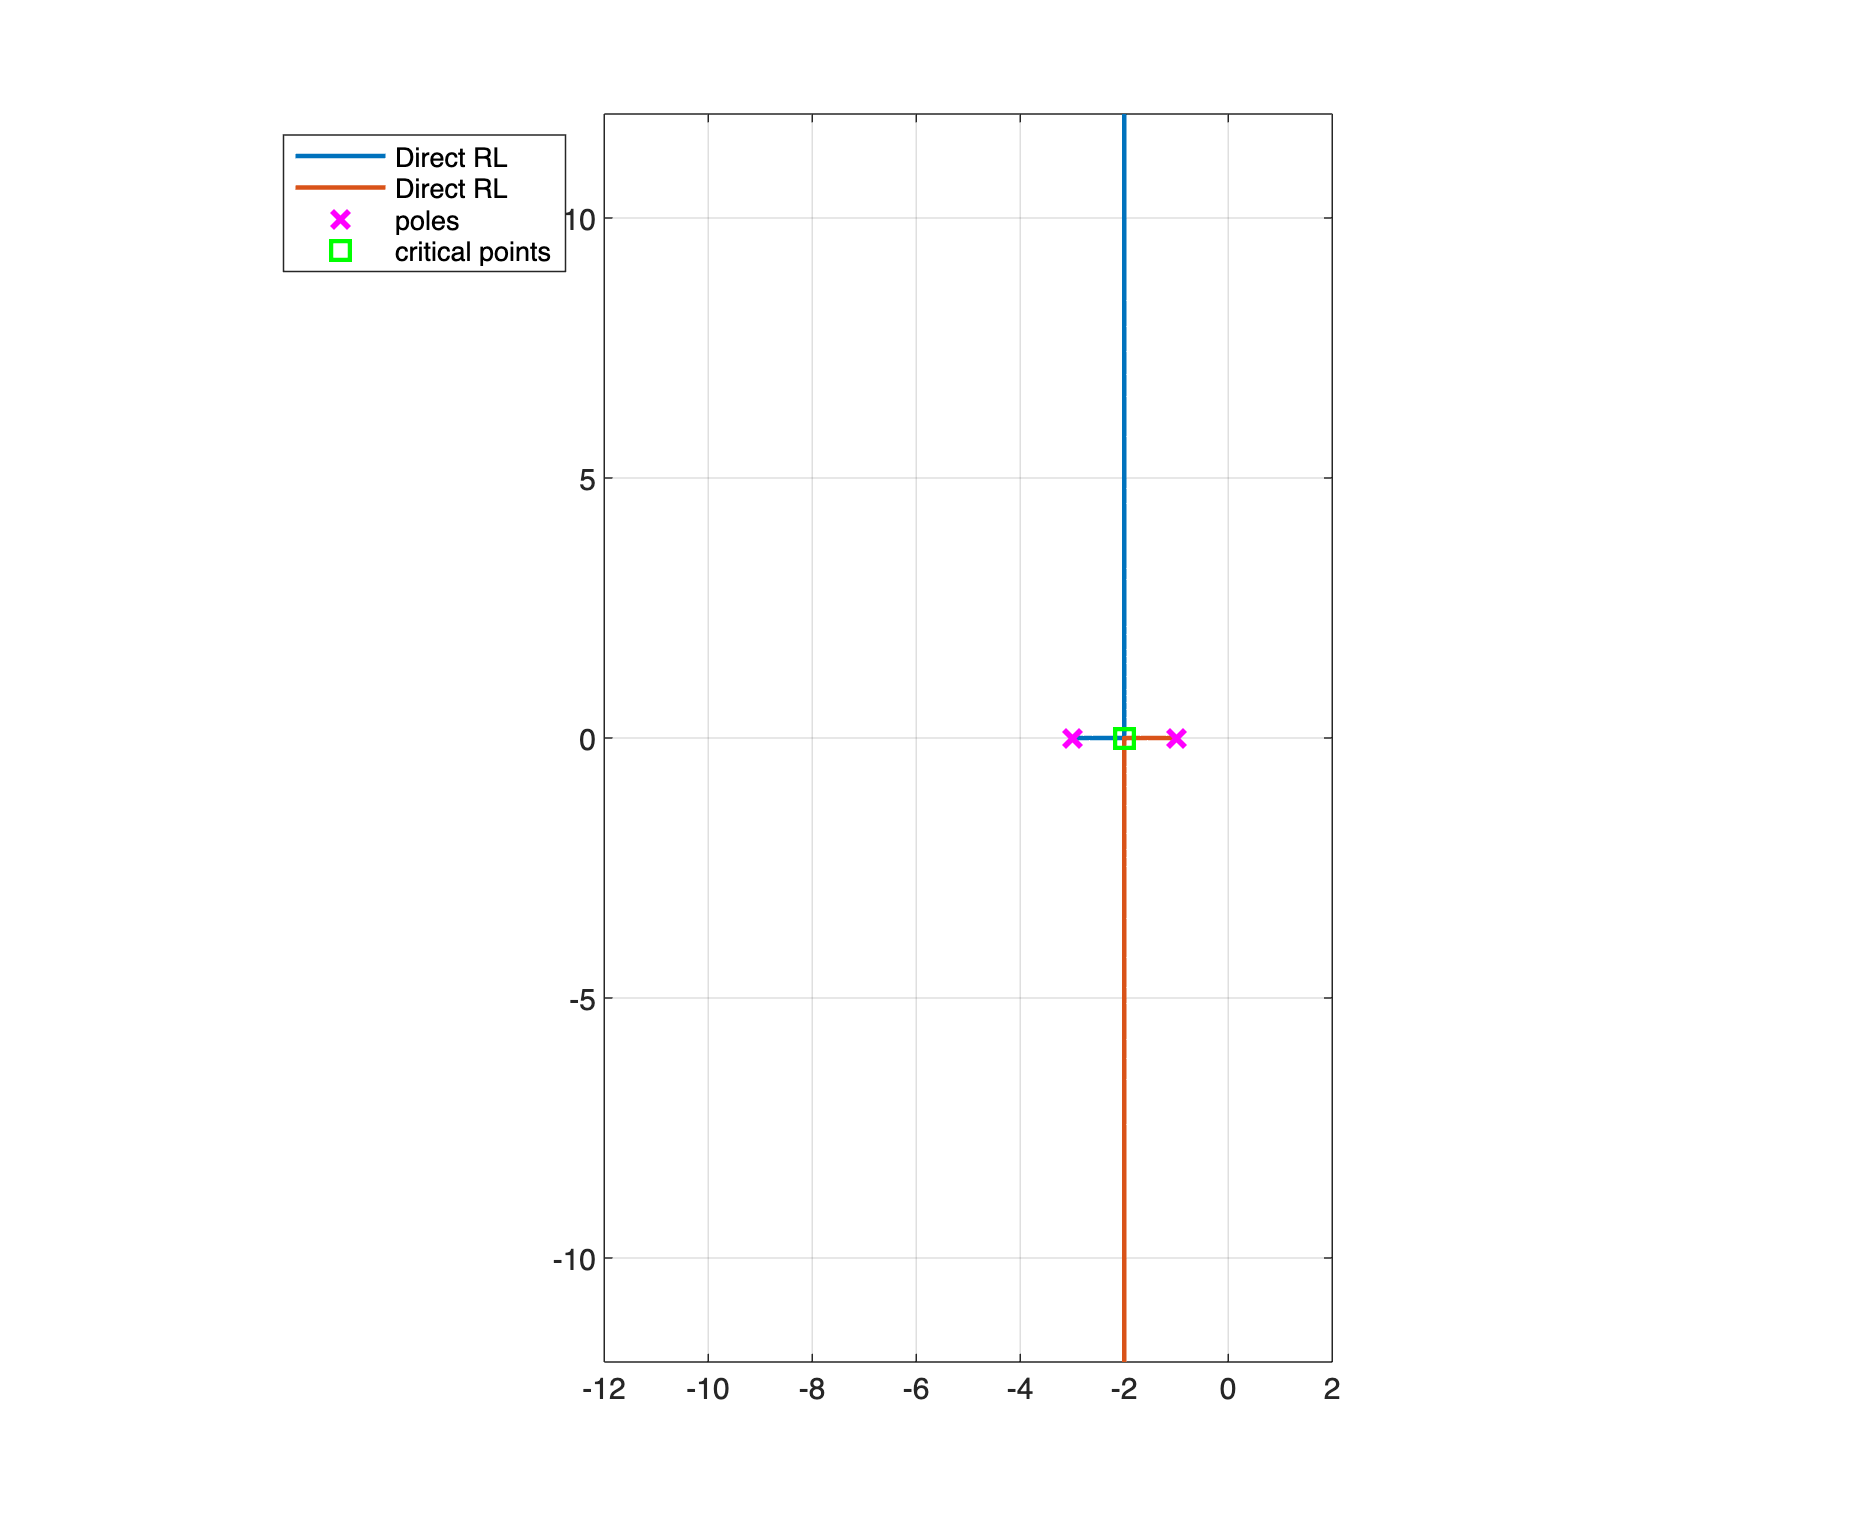


% =========================================================
% Let's determine the critical points using the Eq. (**ALT) 
criticalPoints0 = DetermineCriticalPointsRL(L0s);
cP_DLset0 = checkCriticPointsDL(criticalPoints0, L0s);
% Which critical point belongs to the Direct Root Locus?
% =========================================================

RL0 = rlocus(L0s); 
% note the structure of RL1: array(n, p)
% where n <--> number of branches (i.e. the degree of the polynomial at
%              denominator)
%       p <--> number of points (closed-loop poles) belonging to each
%              branch, i.e. number of values fo the gain rho used to
%              determine the Direct Locus
hfRL0 = figure('Units','centimeters','Position',[0.1, 0.1, 22, 18]);
% the Direct RL
n = size(RL0, 1); % how many branches?
for k=1:n
    h_rld1(k,1) = plot( real(RL0(k,:)),imag(RL0(k,:)),'LineWidth',1.5 );
    hold on;
end % for k

% zeros & poles and then singular points
h_s0 = plot(real(zL0),imag(zL0),'mo', ...
    real(pL0),imag(pL0),'mx', ...
    real(cP_DLset0), imag(cP_DLset0), 'gs', ...
    'MarkerSize',8, 'LineWidth',2);

grid on; hold off; axis equal;
axis([-12,2,-12, 12]);
LocusLeg = cell(1,n);
for k=1:n
    LocusLeg{1,k} = 'Direct RL';
end % for k
legend([LocusLeg, {'poles','critical points'}], 'Location', 'best')

% zeros & poles
zLa = zero(La_s);
pLa = pole(La_s);

% asymptotes & centroid
n = numel(pLa); % the degree of the polynomial at the denominator in the TF
m = numel(zLa); % the degree of the polynomial at the nuumerator in the TF
% the centroid
x_aA = (1/(n-m))*(sum(pLa) - sum(zLa))

x_aA = -4.0000


% the asymptotes belonging to the DL
k = (0:n-m-1);
theta_aA = (180/(n-m))*(2.*k+1)

theta_aA =     90   270


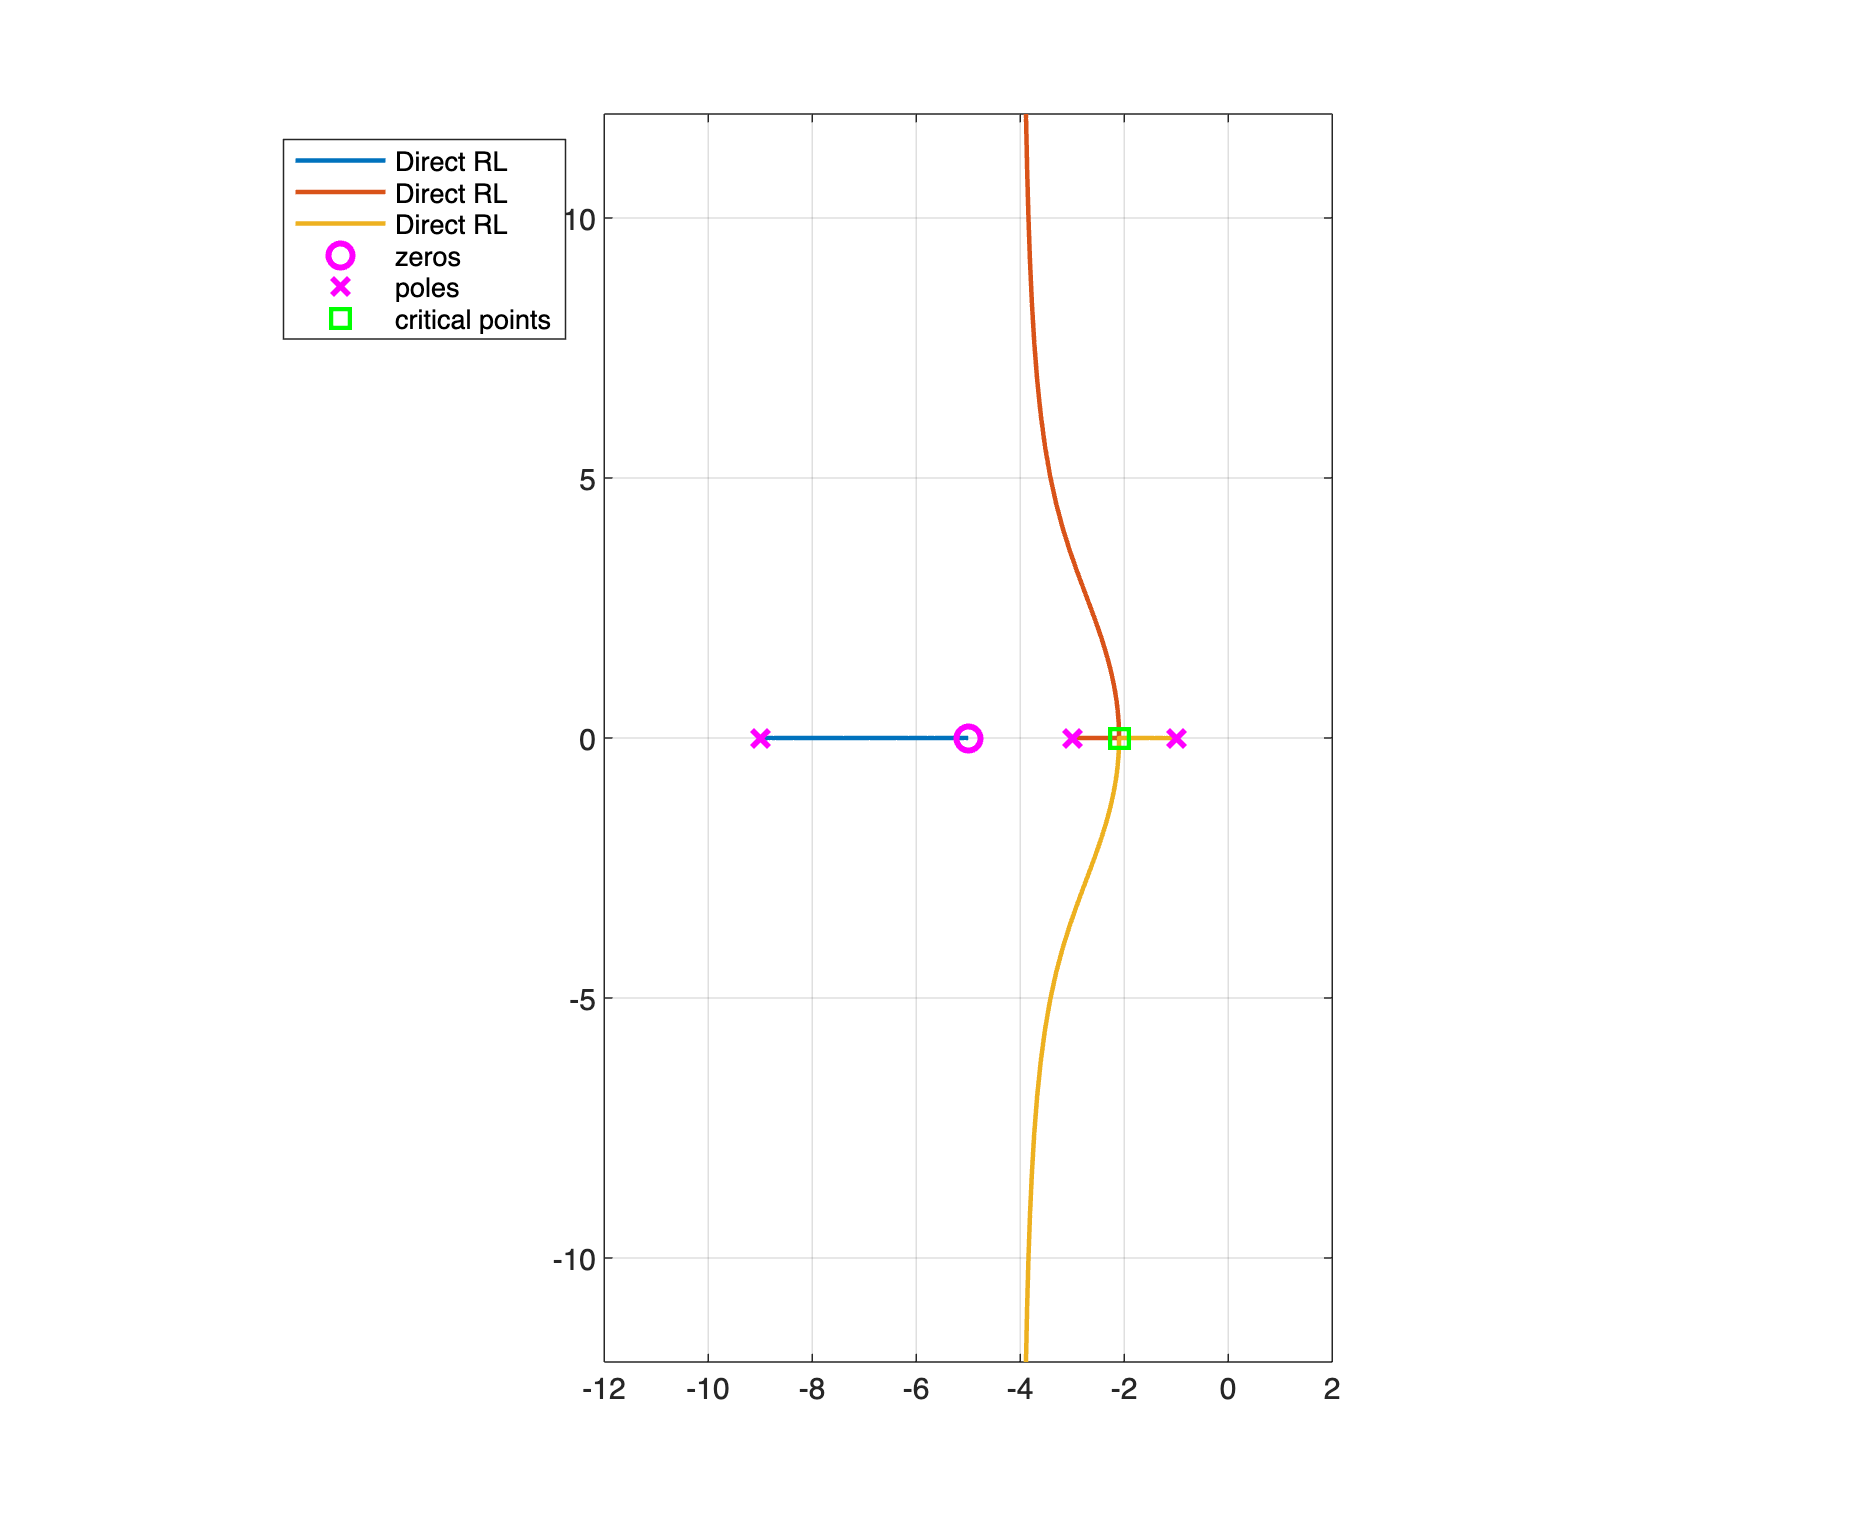


% =========================================================
% Let's determine the critical points using the Eq. (**ALT) 
criticalPoints_A = DetermineCriticalPointsRL(La_s);
cP_DLset_A = checkCriticPointsDL(criticalPoints_A, La_s);
% Which critical point belongs to the Direct Root Locus?
% =========================================================

RL_A = rlocus(La_s); 
% note the structure of RL1: array(n, p)
% where n <--> number of branches (i.e. the degree of the polynomial at
%              denominator)
%       p <--> number of points (closed-loop poles) belonging to each
%              branch, i.e. number of values fo the gain rho used to
%              determine the Direct Locus
hfRL_A = figure('Units','centimeters','Position',[0.1, 0.1, 22, 18]);
% the Direct RL
n = size(RL_A, 1); % how many branches?
for k=1:n
    h_rld1(k,1) = plot( real(RL_A(k,:)),imag(RL_A(k,:)),'LineWidth',1.5 );
    hold on;
end % for k

% zeros & poles and then singular points
h_s_A = plot(real(zLa),imag(zLa),'mo', ...
    real(pLa),imag(pLa),'mx', ...
    real(cP_DLset_A), imag(cP_DLset_A), 'gs', ...
    'MarkerSize',8, 'LineWidth',2);

grid on; hold off; axis equal;
axis([-12,2,-12, 12]); 
LocusLeg = cell(1,n);
for k=1:n
    LocusLeg{1,k} = 'Direct RL';
end % for k
legend([LocusLeg, {'zeros','poles','critical points'}], 'Location', 'best')

% zeros & poles
zLb = zero(Lb_s);
pLb = pole(Lb_s);

% asymptotes & centroid
n = numel(pLb); % the degree of the polynomial at the denominator in the TF
m = numel(zLb); % the degree of the polynomial at the nuumerator in the TF
% the centroid
x_aB = (1/(n-m))*(sum(pLb) - sum(zLb))

x_aB = -1.7764e-15


% the asymptotes belonging to the DL
k = (0:n-m-1);
theta_aB = (180/(n-m))*(2.*k+1)

theta_aB =     90   270


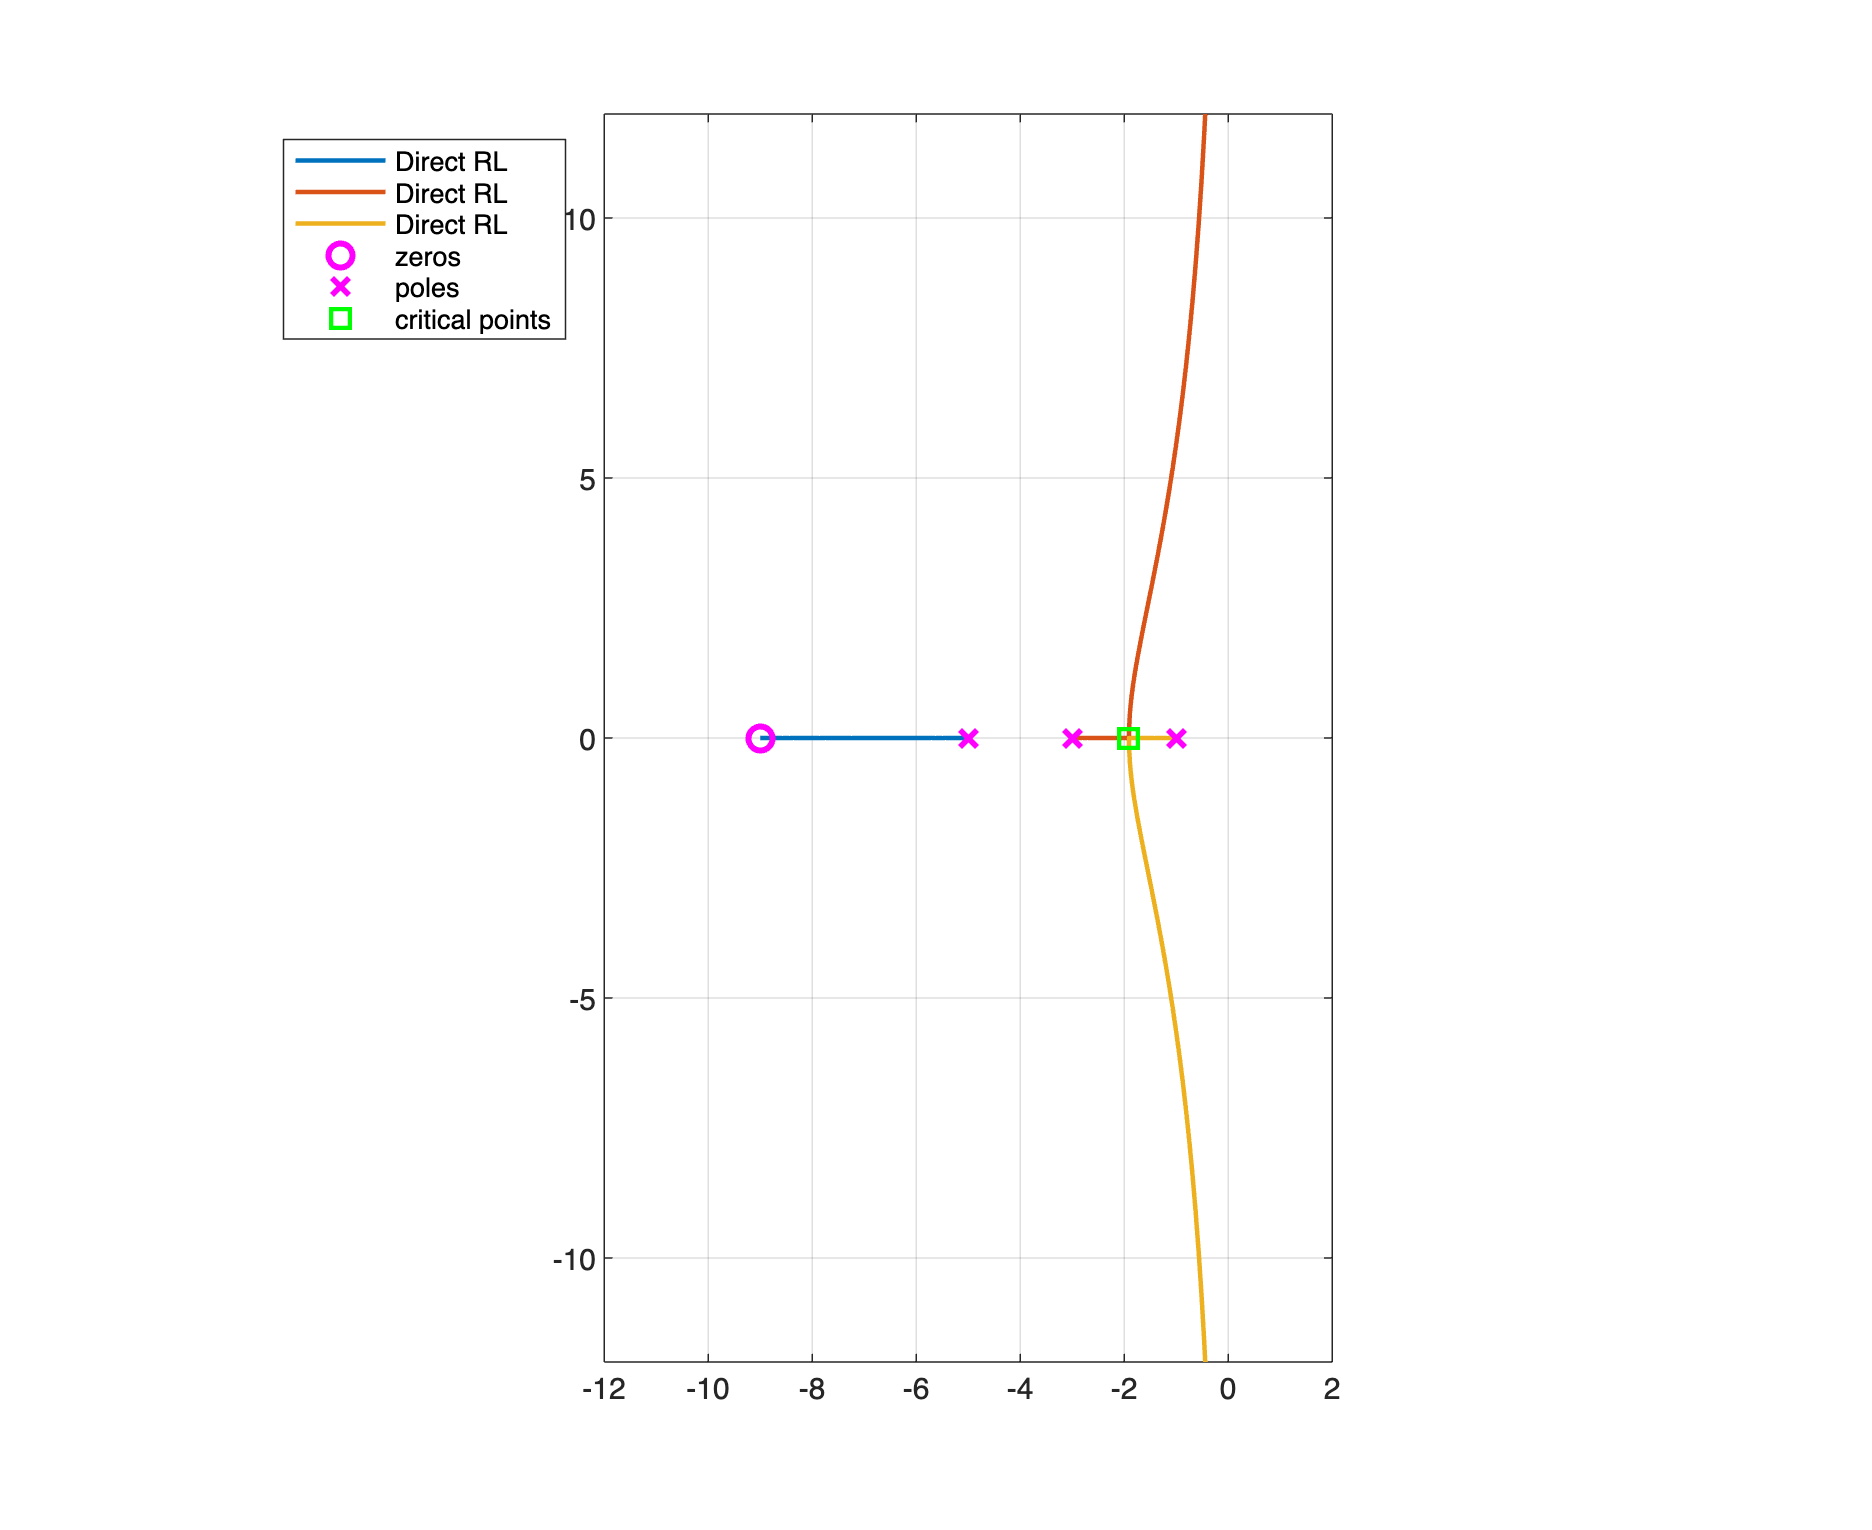


% =========================================================
% Let's determine the critical points using the Eq. (**ALT) 
criticalPoints_B = DetermineCriticalPointsRL(Lb_s);
cP_DLset_B = checkCriticPointsDL(criticalPoints_B, Lb_s);
% Which critical point belongs to the Direct Root Locus?
% =========================================================

RL_B = rlocus(Lb_s); 
% note the structure of RL1: array(n, p)
% where n <--> number of branches (i.e. the degree of the polynomial at
%              denominator)
%       p <--> number of points (closed-loop poles) belonging to each
%              branch, i.e. number of values fo the gain rho used to
%              determine the Direct Locus
hfRL_B = figure('Units','centimeters','Position',[0.1, 0.1, 22, 18]);
% the Direct RL
n = size(RL_B, 1); % how many branches?
for k=1:n
    h_rld1(k,1) = plot( real(RL_B(k,:)),imag(RL_B(k,:)),'LineWidth',1.5 );
    hold on;
end % for k

% zeros & poles and then singular points
h_s_B = plot(real(zLb),imag(zLb),'mo', ...
    real(pLb),imag(pLb),'mx', ...
    real(cP_DLset_B), imag(cP_DLset_B), 'gs', ...
    'MarkerSize',8, 'LineWidth',2);

grid on; hold off; axis equal;
axis([-12,2,-12, 12]); 
LocusLeg = cell(1,n);
for k=1:n
    LocusLeg{1,k} = 'Direct RL';
end % for k
legend([LocusLeg, {'zeros','poles','critical points'}], 'Location', 'best')

Let's consider a set of $\varrho$ values, visualise the corresponding closed-loop poles on the Direct Root Locus and investigate about the performance of the closed-loop system corresponding to each $\varrho$ value:

rhoSET = linspace(6e-2, 6.0e1, 10); % 20 values for the gain rho, from 10^(-2) to 10^4
rhoSET = [rhoSET, 1000];
closedLoopPoles0 = rlocus(L0s, rhoSET);
closedLoopPolesA = rlocus(La_s, rhoSET);
closedLoopPolesB = rlocus(Lb_s, rhoSET);

#### Closed-Loop Performance Analysis

Let's determine the open-loop and the closed-loop transfer functions corresponding to each $\varrho$ value:

r = numel(rhoSET);
OL0_tf = cell(r, 1); % to store the Open-Loop TFs
OLA_tf = cell(r, 1); % to store the Open-Loop TFs
OLB_tf = cell(r, 1); % to store the Open-Loop TFs
CL0_tf = cell(r, 1); % to store the Closed-Loop TFs
CLA_tf = cell(r, 1); % to store the Closed-Loop TFs
CLB_tf = cell(r, 1); % to store the Closed-Loop TFs

for i=1:r
    OL0_tf{i} = rhoSET(i)*L0s;
    OLA_tf{i} = rhoSET(i)*La_s;
    OLB_tf{i} = rhoSET(i)*Lb_s;
    CL0_tf{i} = feedback(OL0_tf{i}, 1, -1);
    CLA_tf{i} = feedback(OLA_tf{i}, 1, -1);
    CLB_tf{i} = feedback(OLB_tf{i}, 1, -1);
end % for i


Now, let's determine the performance for each transfer function.

STABmargins0 = cell(r, 1);
STEPperformance0 =  cell(r, 1);
CLpoles0 = cell(r, 1);

STABmarginsA = cell(r, 1);
STEPperformanceA =  cell(r, 1);
CLpolesA = cell(r, 1);

STABmarginsB = cell(r, 1);
STEPperformanceB =  cell(r, 1);
CLpolesB = cell(r, 1);

tSET = (0:1e-3:6); % a set of time instants, used to obtain 
                    % an accurate estimation of the settling time etc.
                    % by applying the stepinfo() function

for ijk = 1:r
    [GmVAL,PmVAL,Wcg,Wcp] = margin(OL0_tf{ijk} );
    STABmargins0{ijk} = struct('Gm', GmVAL, ...
                               'GainFreq', Wcg, ...
                               'Pm', PmVAL, ...
                               'PhaseFreq', Wcp);
    CLpoles0{ijk} = pole(CL0_tf{ijk});
    [ySTEP, tSTEP] = step(CL0_tf{ijk},tSET);
    res = stepinfo(ySTEP, tSTEP,  'SettlingTimeThreshold',0.01);
    STEPperformance0{ijk} = struct('RiseT', res.RiseTime, ...
                                   'SettlingT', res.SettlingTime, ...
                                   'OverShoot', res.Overshoot);

    [GmVAL,PmVAL,Wcg,Wcp] = margin(OLA_tf{ijk} );
    STABmarginsA{ijk} = struct('Gm', GmVAL, ...
                               'GainFreq', Wcg, ...
                               'Pm', PmVAL, ...
                               'PhaseFreq', Wcp);
    CLpolesA{ijk} = pole(CLA_tf{ijk});
    res = stepinfo(CLA_tf{ijk}, 'SettlingTimeThreshold',0.01);
    STEPperformanceA{ijk} = struct('RiseT', res.RiseTime, ...
                                   'SettlingT', res.SettlingTime, ...
                                   'OverShoot', res.Overshoot);

    [GmVAL,PmVAL,Wcg,Wcp] = margin(OLB_tf{ijk} );
    STABmarginsB{ijk} = struct('Gm', GmVAL, ...
                               'GainFreq', Wcg, ...
                               'Pm', PmVAL, ...
                               'PhaseFreq', Wcp);
    CLpolesB{ijk} = pole(CLB_tf{ijk});
    res = stepinfo(CLB_tf{ijk}, 'SettlingTimeThreshold',0.01);
    STEPperformanceB{ijk} = struct('RiseT', res.RiseTime, ...
                                   'SettlingT', res.SettlingTime, ...
                                   'OverShoot', res.Overshoot);
end % for ijk

Finally, let's fill a table with the results:

results0 = zeros(r, 8);
resultsA = zeros(r, 8);
resultsB = zeros(r, 8);

for m = 1:r
    results0(m, 1) = rhoSET(m);

    results0(m, 2) = STABmargins0{m}.Pm;
    results0(m, 3) = STABmargins0{m}.PhaseFreq;
    results0(m, 4) = STABmargins0{m}.Gm;
    results0(m, 5) = STABmargins0{m}.GainFreq;

    results0(m, 6) = STEPperformance0{m}.SettlingT;
    results0(m, 7) = STEPperformance0{m}.OverShoot;
    results0(m, 8) = STEPperformance0{m}.RiseT;

    resultsA(m, 1) = rhoSET(m);

    resultsA(m, 2) = STABmarginsA{m}.Pm;
    resultsA(m, 3) = STABmarginsA{m}.PhaseFreq;
    resultsA(m, 4) = STABmarginsA{m}.Gm;
    resultsA(m, 5) = STABmarginsA{m}.GainFreq;

    resultsA(m, 6) = STEPperformanceA{m}.SettlingT;
    resultsA(m, 7) = STEPperformanceA{m}.OverShoot;
    resultsA(m, 8) = STEPperformanceA{m}.RiseT;

    resultsB(m, 1) = rhoSET(m);

    resultsB(m, 2) = STABmarginsB{m}.Pm;
    resultsB(m, 3) = STABmarginsB{m}.PhaseFreq;
    resultsB(m, 4) = STABmarginsB{m}.Gm;
    resultsB(m, 5) = STABmarginsB{m}.GainFreq;

    resultsB(m, 6) = STEPperformanceB{m}.SettlingT;
    resultsB(m, 7) = STEPperformanceB{m}.OverShoot;
    resultsB(m, 8) = STEPperformanceB{m}.RiseT;
    
    
end % for m

REStable1_0 = array2table([results0(:,1),results0(:,6:8)], "VariableNames",...
    {' Gain Rho', 'Step Resp. Settling Time', ...
     'Step Resp. Overshoot', 'Step Resp. Rise Time'})

REStable1_0 = 11×4 table
     Gain Rho    Step Resp. Settling Time    Step Resp. Overshoot    Step Resp. Rise Time
    _________    ________________________    ____________________    ____________________
       0.06               4.6183                         0                  2.3075       
       6.72               2.0572                    7.2289                 0.62848       
      13.38               2.1711                    16.767                 0.40185       
      20.04               2.3275                    23.695                 0.31042       
       26.7               2.1084                    28.956                 0.25936       
      33.36               2.3146                    33.136                 0.22611       
      40.02               2.1786                    36.574                 0.20243       
      46.68               2.0


REStable1_A = array2table([resultsA(:,1),resultsA(:,6:8)], "VariableNames",...
    {' Gain Rho', 'Step Resp. Settling Time', ...
     'Step Resp. Overshoot', 'Step Resp. Rise Time'})

REStable1_A = 11×4 table
     Gain Rho    Step Resp. Settling Time    Step Resp. Overshoot    Step Resp. Rise Time
    _________    ________________________    ____________________    ____________________
       0.06               4.8398                         0                  2.3145       
       6.72               1.5202                    0.7356                 0.91646       
      13.38               1.8349                    4.0609                 0.57442       
      20.04               1.4972                     7.507                 0.42766       
       26.7                1.265                    10.623                 0.34663       
      33.36               1.5047                    13.406                 0.29489       
      40.02               1.4127                    15.908                 0.25889       
      46.68               1.3


REStable1_B = array2table([resultsB(:,1),resultsB(:,6:8)], "VariableNames",...
    {' Gain Rho', 'Step Resp. Settling Time', ...
     'Step Resp. Overshoot', 'Step Resp. Rise Time'})

REStable1_B = 11×4 table
     Gain Rho    Step Resp. Settling Time    Step Resp. Overshoot    Step Resp. Rise Time
    _________    ________________________    ____________________    ____________________
       0.06               4.8676                         0                   2.3285      
       6.72               3.2523                    22.447                  0.45562      
      13.38               3.7704                    37.874                  0.30631      
      20.04               4.2798                    47.379                  0.24446      
       26.7               4.4112                    53.925                  0.20901      
      33.36               4.9291                     58.86                  0.18513      
      40.02               5.4087                    62.683                  0.16817      
      46.68               5.8



REStable2_0 = cell2table([num2cell(results0(:,1)),CLpoles0], "VariableNames",...
    {' Gain Rho', 'Closed-Loop Poles'})

REStable2_0 = 11×2 table
     Gain Rho    Closed-Loop Poles
    _________    _________________
       0.06        {2×1 double}   
       6.72        {2×1 double}   
      13.38        {2×1 double}   
      20.04        {2×1 double}   
       26.7        {2×1 double}   
      33.36        {2×1 double}   
      40.02        {2×1 double}   
      46.68        {2×1 double}   
      53.34        {2×1 double}   
         60        {2×1 double}   
       1000        {2×1 double}   


REStable2_A = cell2table([num2cell(resultsA(:,1)),CLpolesA], "VariableNames",...
    {' Gain Rho', 'Closed-Loop Poles'})

REStable2_A = 11×2 table
     Gain Rho    Closed-Loop Poles
    _________    _________________
       0.06        {3×1 double}   
       6.72        {3×1 double}   
      13.38        {3×1 double}   
      20.04        {3×1 double}   
       26.7        {3×1 double}   
      33.36        {3×1 double}   
      40.02        {3×1 double}   
      46.68        {3×1 double}   
      53.34        {3×1 double}   
         60        {3×1 double}   
       1000        {3×1 double}   


REStable2_B = cell2table([num2cell(resultsB(:,1)),CLpolesB], "VariableNames",...
    {' Gain Rho', 'Closed-Loop Poles'})

REStable2_B = 11×2 table
     Gain Rho    Closed-Loop Poles
    _________    _________________
       0.06        {3×1 double}   
       6.72        {3×1 double}   
      13.38        {3×1 double}   
      20.04        {3×1 double}   
       26.7        {3×1 double}   
      33.36        {3×1 double}   
      40.02        {3×1 double}   
      46.68        {3×1 double}   
      53.34        {3×1 double}   
         60        {3×1 double}   
       1000        {3×1 double}   



REStable3_0 = array2table([results0(:,1:5)], "VariableNames",...
    {' Gain Rho', 'Phase Margin', 'Ph. Marg. Ang. Freq.', ...
     'Gaim Margin', 'G. Marg. Ang. Freq.'})

REStable3_0 = 11×5 table
     Gain Rho    Phase Margin    Ph. Marg. Ang. Freq.    Gaim Margin    G. Marg. Ang. Freq.
    _________    ____________    ____________________    ___________    ___________________
       0.06            Inf                 NaN               Inf                Inf        
       6.72         91.532              1.6794               Inf                Inf        
      13.38         63.524              2.9942               Inf                Inf        
      20.04         51.646              3.9288               Inf                Inf        
       26.7          44.64              4.6902               Inf                Inf        
      33.36         39.883              5.3478               Inf                Inf        
      40.02         36.382              5.9346               Inf     


REStable3_A = array2table([resultsA(:,1:5)], "VariableNames",...
    {' Gain Rho', 'Phase Margin', 'Ph. Marg. Ang. Freq.', ...
     'Gaim Margin', 'G. Marg. Ang. Freq.'})

REStable3_A = 11×5 table
     Gain Rho    Phase Margin    Ph. Marg. Ang. Freq.    Gaim Margin    G. Marg. Ang. Freq.
    _________    ____________    ____________________    ___________    ___________________
       0.06            Inf                 NaN               Inf                Inf        
       6.72         135.45             0.69901               Inf                Inf        
      13.38         93.442              1.9391               Inf                Inf        
      20.04         78.641              2.7967               Inf                Inf        
       26.7         70.132              3.5152               Inf                Inf        
      33.36         64.338              4.1512               Inf                Inf        
      40.02         60.001               4.731               Inf     


REStable3_B = array2table([resultsB(:,1:5)], "VariableNames",...
    {' Gain Rho', 'Phase Margin', 'Ph. Marg. Ang. Freq.', ...
     'Gaim Margin', 'G. Marg. Ang. Freq.'})

REStable3_B = 11×5 table
     Gain Rho    Phase Margin    Ph. Marg. Ang. Freq.    Gaim Margin    G. Marg. Ang. Freq.
    _________    ____________    ____________________    ___________    ___________________
       0.06            Inf                 NaN               Inf                Inf        
       6.72         58.374              2.6182               Inf                Inf        
      13.38         36.258              3.9959               Inf                Inf        
      20.04         26.721              4.9521               Inf                Inf        
       26.7         21.204              5.7175               Inf                Inf        
      33.36         17.554              6.3711               Inf                Inf        
      40.02         14.945              6.9497               Inf     

## Other Use of the Root Locus - Generalised Root Locus

The **root locus** can be applied to **any polynomial** with a single parameter varying linearly.

### Example: a Spring-Mass-Damper System

We want to explore the influence of some parameters on the system’s dynamics represented by the following characteristic polynomial


$$M s^2+ \mu s +k = 0$$


- What if we vary the spring stiffness?

- What if we vary the damping effect?

**Varying the spring stiffness**: let's suppose $k \in [0,\, +\infty)$, and assume $M$ and $\mu$ as constant parameters


$$p(s,\,k) = Ms^2+\mu s +k = (Ms+\mu)s +k = 0 \quad \Longrightarrow \quad 
\frac{1}{s(Ms+\mu)} = -\frac{1}{k}$$


**Varying the damping coefficient**; let's suppose this time $\mu \in [0,\, +\infty)$, and assume $M$ and $k$ as constant parameters


$$p(s,\,\mu) = Ms^2+\mu s +k = (Ms^2+k) +\mu s = 0 \quad \Longrightarrow \quad 
\frac{s}{Ms^2+k} = -\frac{1}{\mu}$$


#### Important Remarks

- in the first scenario, as $k$ increases (the spring becomes stiffer and stiffer), the poles are complex with constant real part, while the imaginary part becomes larger;

- in the second scenario, the poles become real as $\mu$ increases, and a slow dominant dynamics arises.

function criticalPoints = DetermineCriticalPointsRL(sysLs)
% criticalPoints = DetermineCriticalPointsRL(sysLs) determines the critical points 
% of the root locus of the SISO system described by the transfer function sysLs, 
% solving the equation (**ALT)
% INPUT: the SISO transfer function sysLs
% OUTPUT: criticalPoints <--> array of complex values, representing the
%                             critical points of both the Direct and
%                             Inverse Root Loci
%
% example: 
% s = tf('s');
% Ls = 1/(s+1)/(s+11);
% cP = DetermineCriticalPointsRL(Ls) % cP = -6
% --------------------------------------------
    if ~issiso(sysLs)
        error('DetermineCriticalPointsRL: only applicable to SISO systems'); 
    end % if
    % now surely it is a SISO system described through transfer function
    %
    
    % let's determine the expression of the critical point equation
    [numP, denP]= tfdata(sysLs,'v'); % let's extract the polynomials 
                                     % from the given transfer function                      
    [PC_EQ, ~] = polyder(numP, denP);% compute the expression (**ALT)
    % and solve it
    PCcandidates = roots(PC_EQ);
    pL = roots(denP);
    % Is there any pole into PCcandidates? If YES, then it is a critical
    % point for sure --> let's add to the set criticalPoints and remove
    % from the set PCcandidates
    preliminaryCP = [];
    CP_denVALS = abs(polyval(denP, PCcandidates));
    poleID = (CP_denVALS <=1e-5); % very close to a pole - numerical approx. of a pole
    if any(poleID)
        preliminaryCP = PCcandidates(poleID);
        PCcandidates(poleID) = [];
    end % if

    LsVALS = polyval(numP, PCcandidates)./polyval(denP, PCcandidates);
    if ~isempty(imag(LsVALS))
        realCHK = (abs(imag(LsVALS))<=1e-10);
        if any(realCHK)
            LsVALS(realCHK) = real(LsVALS(realCHK));
        end % if
        realFLAG = realCHK;
    else
        realFLAG = false(size(realCHK));
    end % if
    % let's evaluate the transfer function for each critical point candidate
    %  bar_s is a critical point iff L(bar_s) is real
    if any(realFLAG)
        criticalPoints = PCcandidates(realFLAG);
    else
        criticalPoints = [];
    end % if
    criticalPoints = [criticalPoints;preliminaryCP ];
end % function

function cP_DLset = checkCriticPointsDL(criticalPoints, Ls)
% given the set of critical points criticalPoints, corresponding 
% to the open-loop transfer function Ls, the function
% checkCriticPointsDL(criticalPoints, L1s) returns the subset of critical
% points belonging to the Direct Root Locus

    [numP, denP]= tfdata(Ls,'v'); % let's extract the polynomials 
                                     % from the given transfer function

    % Is there any pole into criticalPoints? If YES, then it is a critical
    % point for sure --> let's add to the set criticalPoints and remove
    % from the set PCcandidates
    preliminaryCP = [];
    CP_denVALS = abs(polyval(denP, criticalPoints));
    poleID = (CP_denVALS <=1e-5); % very close to a pole - numerical approx. of a pole
    if any(poleID)
        preliminaryCP = criticalPoints(poleID);
        criticalPoints(poleID) = [];
    end % if

    % Is there any zero into criticalPoints? If YES, then it is a critical
    % point for sure --> let's add to the set criticalPoints and remove
    % from the set PCcandidates
    CP_numVALS = abs(polyval(numP, criticalPoints));
    zeroID = (CP_numVALS <=1e-5); % very close to a zero - numerical approx. of a zero
    if any(zeroID)
        preliminaryCP = [preliminaryCP;criticalPoints(zeroID)];
        criticalPoints(zeroID) = [];
    end % if
                                
    LsVALS = polyval(numP, criticalPoints)./polyval(denP, criticalPoints);
    D_RL_FLAG = (LsVALS < 0); % the root locus eq. is L(s) = -1/rho
                              % thus if rho >0 then L(s) is a negative real
                              % value
    if any(D_RL_FLAG)                          
        cP_DLset = criticalPoints(D_RL_FLAG);   
    else
        cP_DLset = [];
    end % if
    cP_DLset = [cP_DLset ; preliminaryCP];
end % function